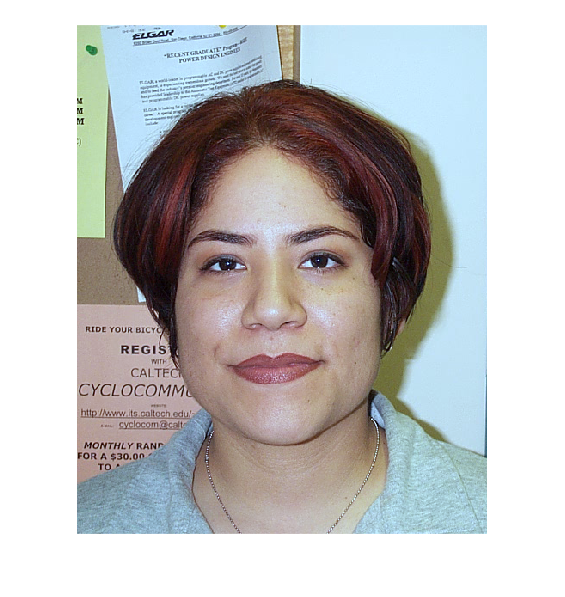

% Read img file
img = imread("..\db\DB0\db0_1.jpg");
img = im2double(img);
% img = imread("..\db\DB1\db1_01.jpg")
% img = imread("..\db\DB2\bl_01.jpg")

%normalize colors
img_gw = greyworld(img);
img_ww = whiteworld(img);


%create facemask
face_mask = facemask(img_gw);

imshow(face_mask)

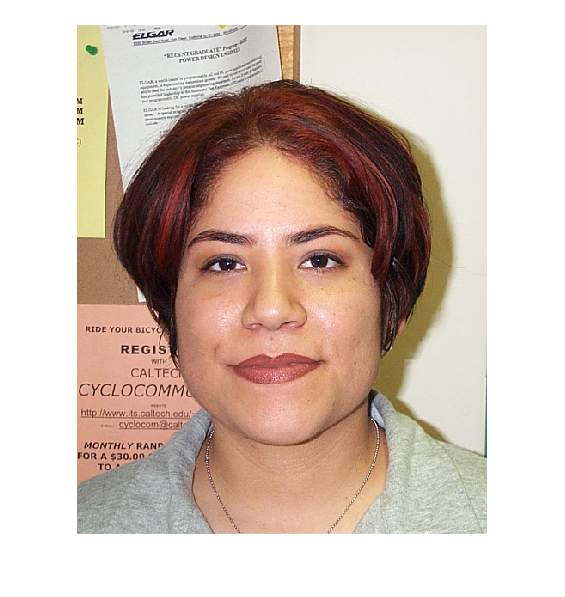


%Cretes an image consisting of only the face.
cropped_face = face_mask .* img;

%Find eyes and a mouth
imshow(cropped_face)